# Labo #1

## Introduction

### Matériel

## 1- Représenter le processus avec ses différents signaux entrée/sortie

In (y) -> Out Extérieur (Z) et Local (Xr)

## Comportement dynamique

### 2- Relevé des données

Ration entre volts et température en ° est égalue à $\frac{1v}{3\degree }$

Valeurs de sorties mesurées en volts pour différentes températures extérieurs.

Temps nécessaire pour faire 63.2% de la température out stable.

Les valeurs en italic sont les valeurs qui sont en dessus de la limite de saturation du capteur.

Pour calculer le temps total pour arriver à la température stable le Tau doit être multiplié par 5.

T = [2:5.4, 4:5.7, 6:6.27, 8:6.75, 10:7.05]

T =      2     3     4     5     4     5     6


T5 = [3.615:3.05, 5.604:4.5, 7.513:5.5, 9.516:5.85,(11.63):(6.35)]


T5 =

  1×0 empty double row vector



T10 = [5.278 (5.33):0.7 (0.9),7.263 (7.33):3.4 (3.5),9.23 (9.33):4.35 (4.45),(11.33):(5.3),(13.33):(5.77)]

T10 =     5.2780    0.9000    7.2630    3.5000    9.2300    4.4500


g =      1     1


Mesures differentes pourTau a 10° ext et 2V chauffage = 0.9 / 0.8 / 0.7 / 0.5 (31.4) / 0.6 (19.3s) / 0.7(119.95) [s]

## 3- Gain statique

### Pour Text 0°


$$\textrm{Gain}=\frac{\Delta \textrm{Output}}{\Delta \textrm{Input}}$$


Input = [2 4 6 8 10]

Input =      2     4     6     8    10


Output = [1.983 3.961 5.955 7.948 9.93]

Output =     1.9830    3.9610    5.9550    7.9480    9.9300


Gain = Output ./ Input

Gain =     0.9915    0.9902    0.9925    0.9935    0.9930


### Caractéristique statique

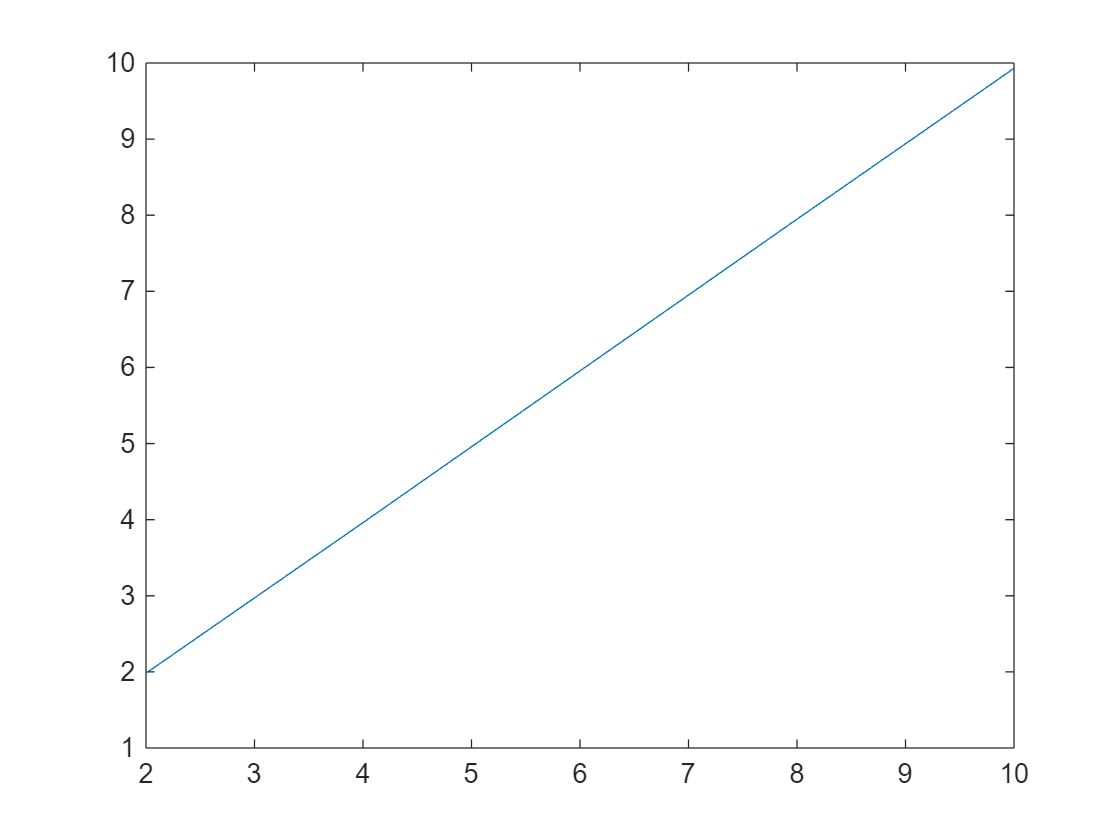

figure;
plot(Input,Output);

### Pour Text 5°


$$T_{\textrm{ext}} =1\ldotp 67V$$


Input = [2,4,6,8,10]

Input =      2     4     6     8    10


Output = [3.585,5.561,7.541,9.527,10.49]

Output =     3.5850    5.5610    7.5410    9.5270   10.4900


Text = 1.67

Text = 1.6700

diff_Output = Output - Text

diff_Output =     1.9150    3.8910    5.8710    7.8570    8.8200


Gain_5 = diff_Output ./ Input

Gain_5 =     0.9575    0.9728    0.9785    0.9821    0.8820


    0.9575    0.9728    0.9785    0.9821    0.8820



### Caractéristique statique

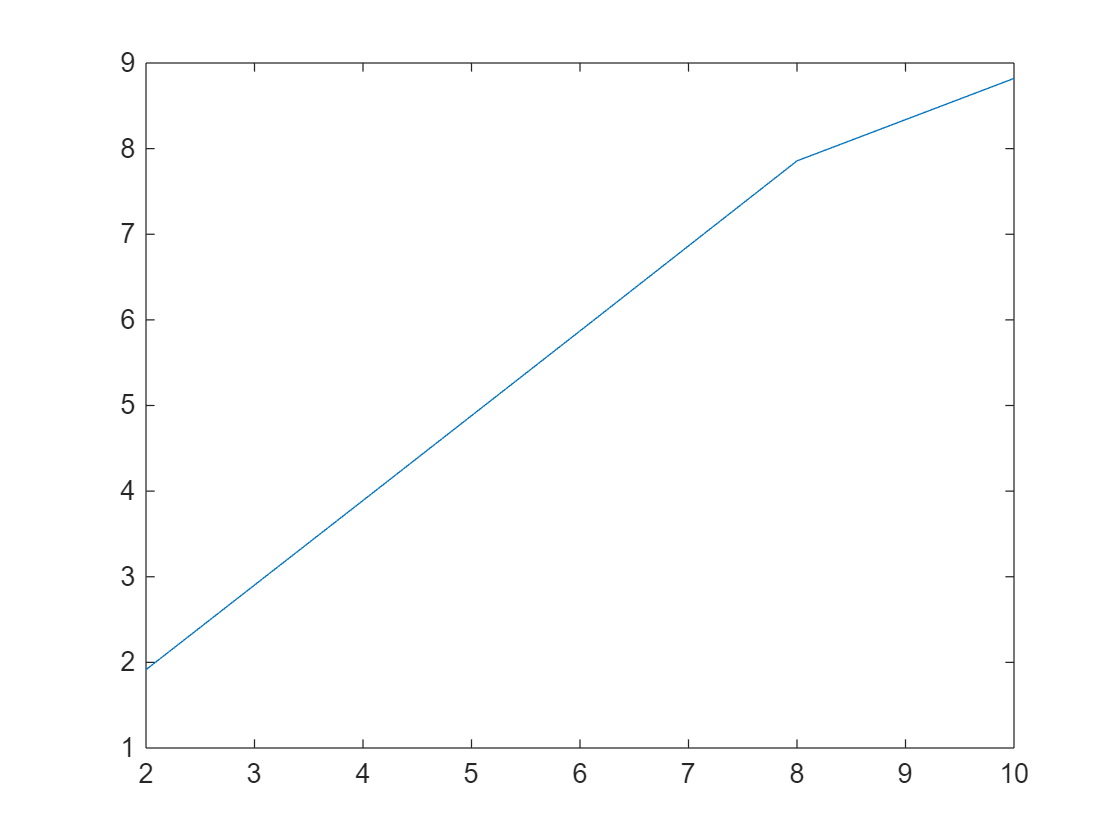

figure;
plot(Input,diff_Output);

### Pour Text 10°


$$T_{\textrm{ext}} =3\ldotp 33V$$


Input = [2,4,6,8,10]

Input =      2     4     6     8    10


Output = [5.203,7.322,9.332,10.49,10.49]

Output =     5.2030    7.3220    9.3320   10.4900   10.4900


Text = 3.33

Text = 3.3300

diff_Output = Output - Text

diff_Output =     1.8730    3.9920    6.0020    7.1600    7.1600


Gain_10 = diff_Output ./ Input

Gain_10 =     0.9365    0.9980    1.0003    0.8950    0.7160


    0.9365    0.9980    1.0003    0.8950    0.7160



### Caractéristique statique

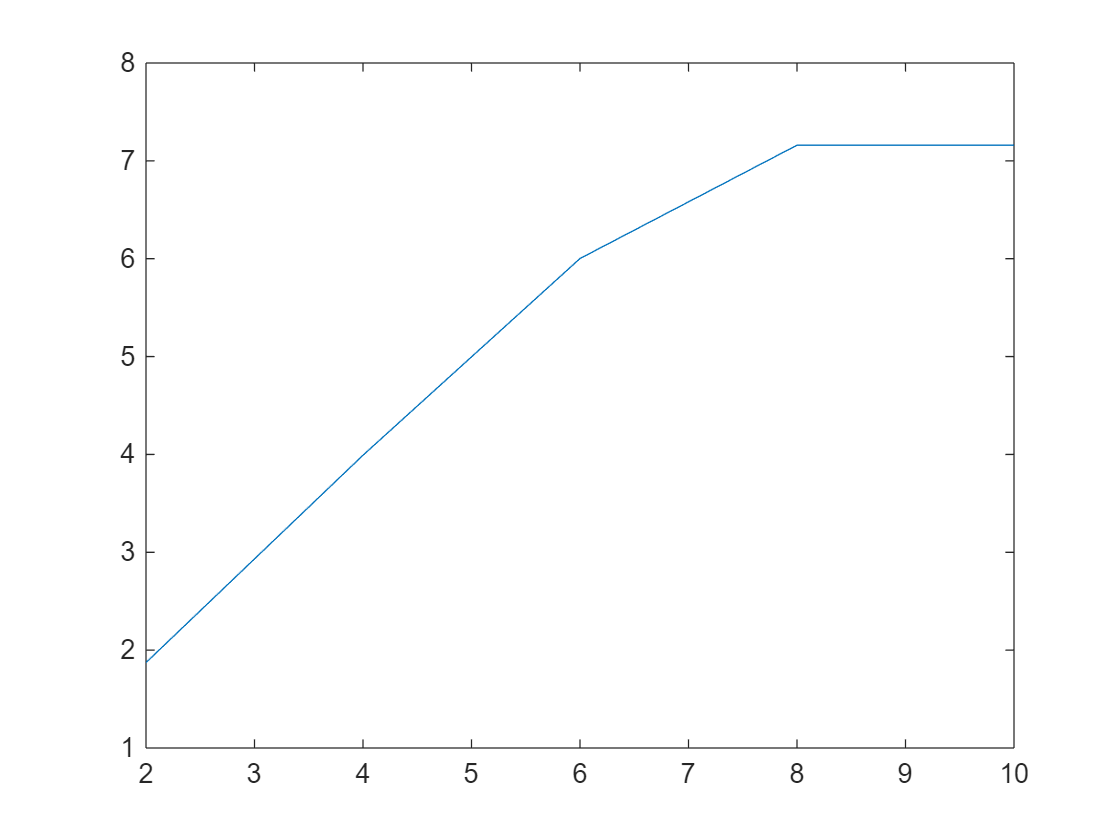

figure;
plot(Input,diff_Output);

## Caractéristique statique

Il s'agit d'un système linéaire 

### 9- Etablir la caractéristique : gain statique = f (Text) pour y=4. S’agit-t-il d’un comportement linéaire ?

Y = 4

Y = 4

Text = [3.961 5.561 7.322]

Text =     3.9610    5.5610    7.3220


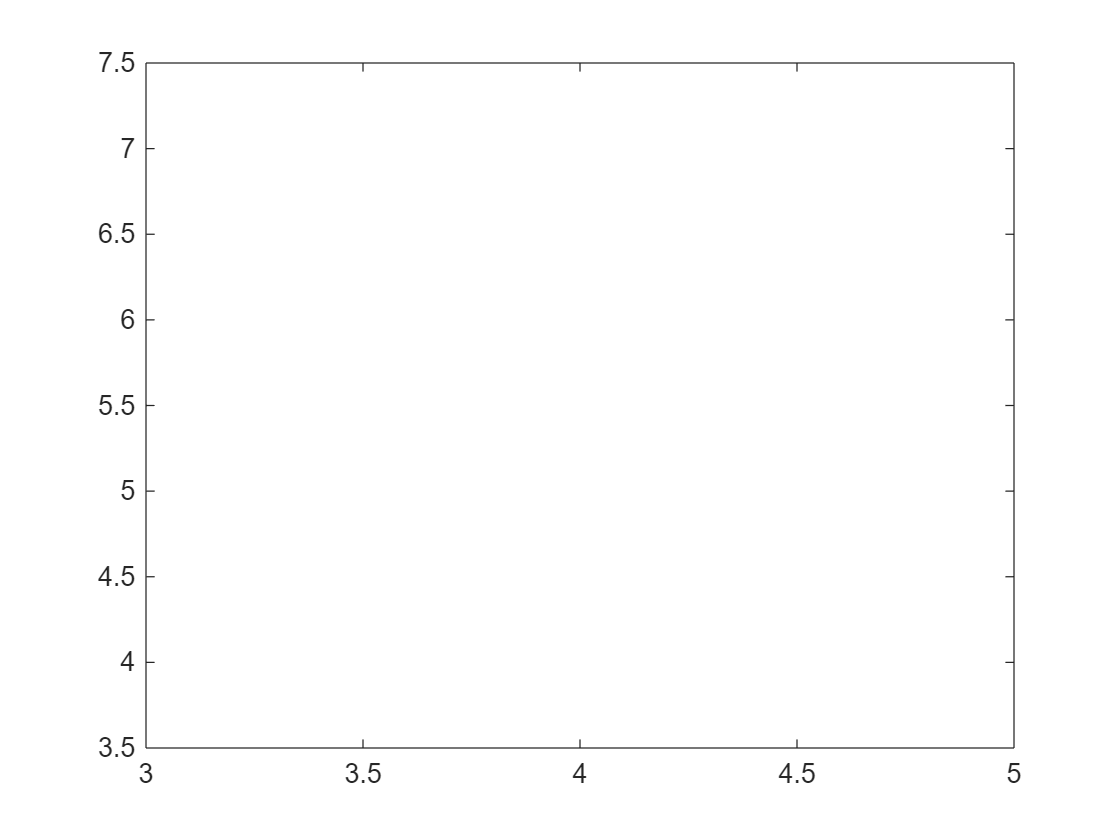

plot(Y,Text)

### 10- Représentez en 3D la caractéristique statique du système (Xr en fonction de y et de Text).

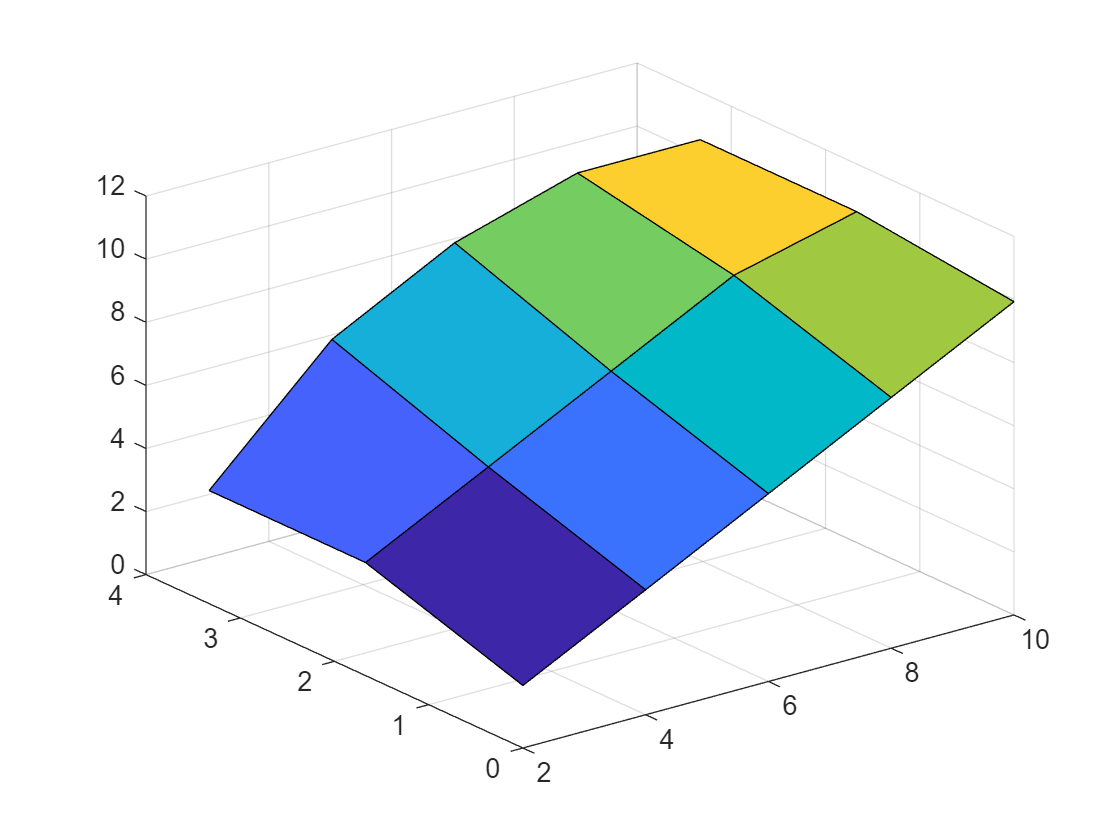

x=[2 4 6 8 10]; 
y=[0 1.67 3.33]; 
z=[1.983 3.961 5.955 7.948 9.93
    3.585 5.561 7.541 9.527 10.49
    3.585 7.322 9.332 10.49 10.49]; 
surf(x,y,z);

### 11. Local innocupé


$$\begin{array}{l}
\frac{14}{3}=4\ldotp 67V\\
\frac{20}{3}=6\ldotp 67V
\end{array}$$


#     Annexe

## Printscreen de courbes de températures du système

### Text = 0°

2V

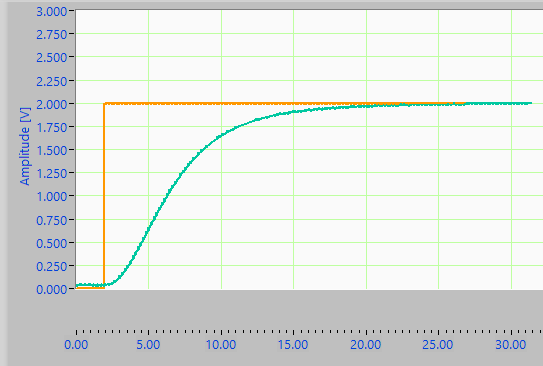

4V

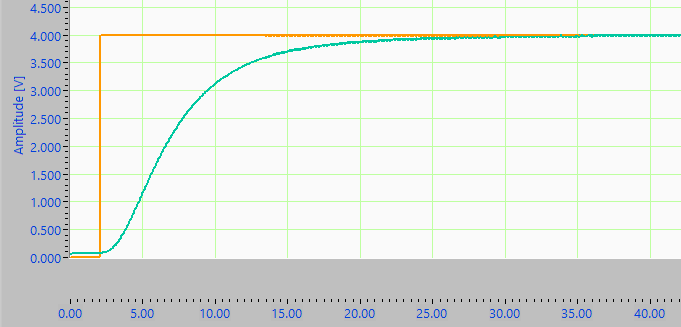

6V

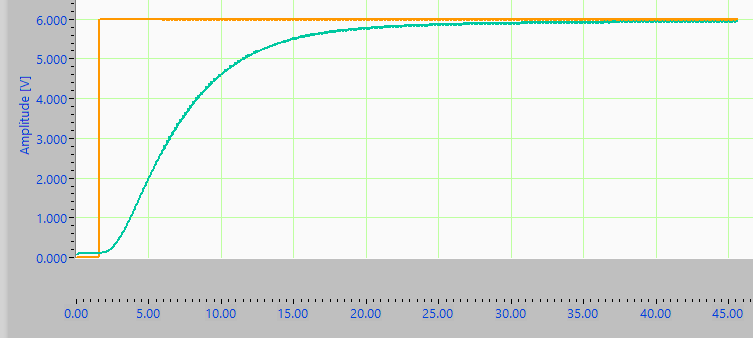

8V

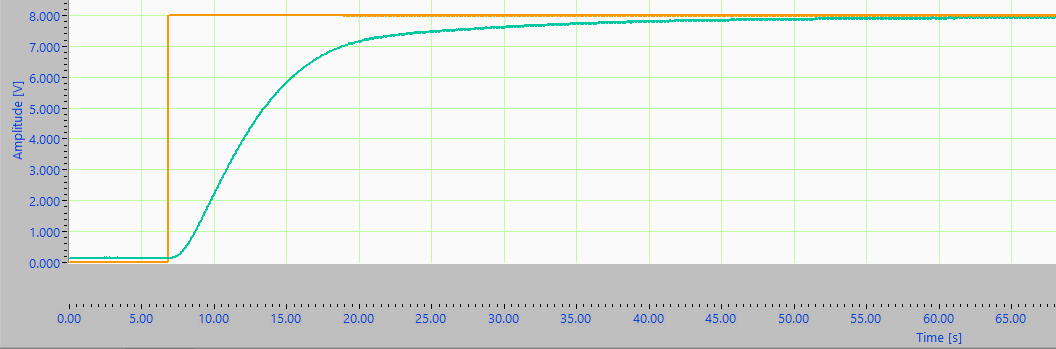

10V

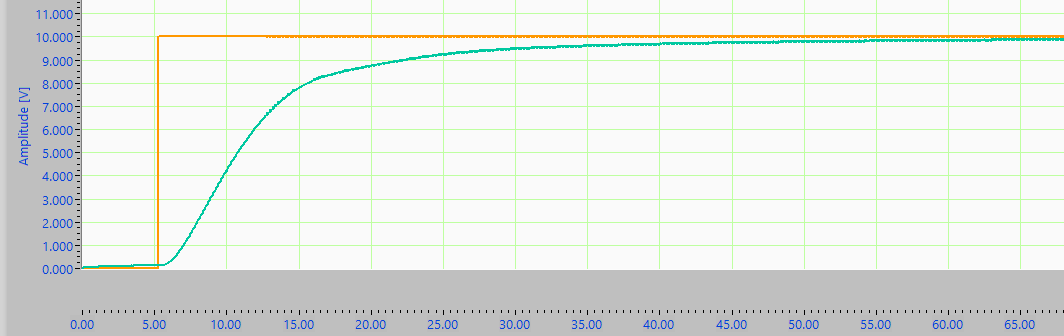

### Text = 5°C

2v

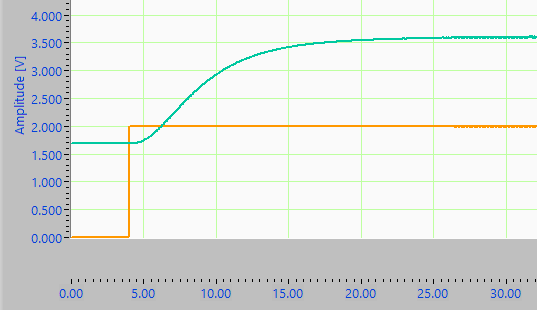

4v

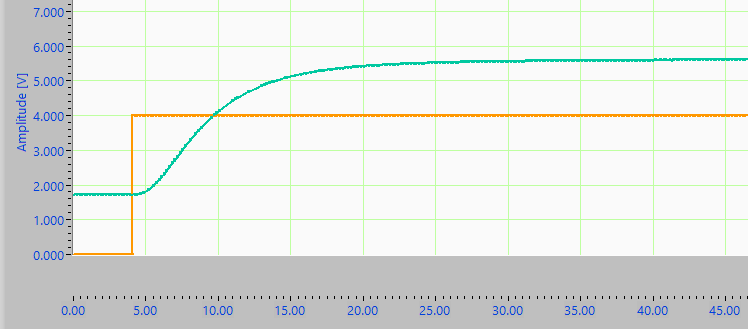

6v

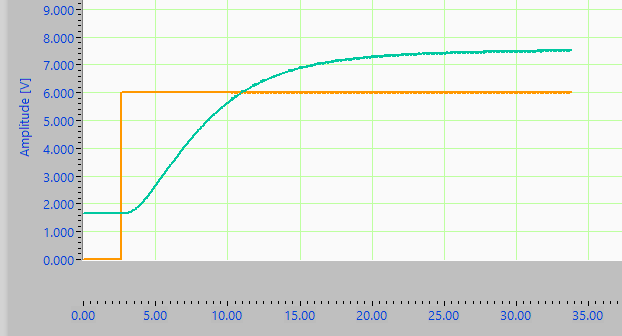

8v

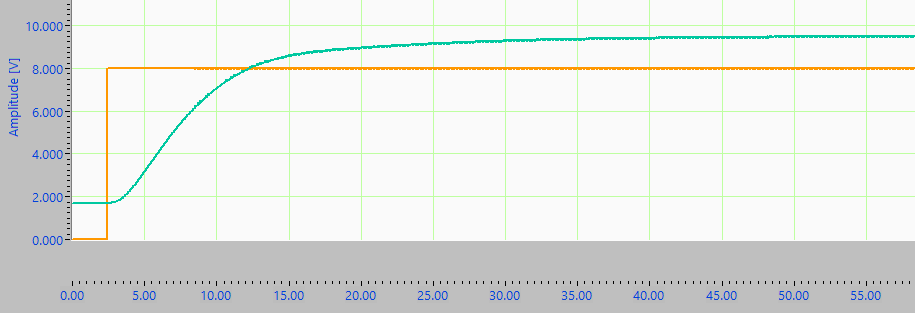

10v (sature)

### 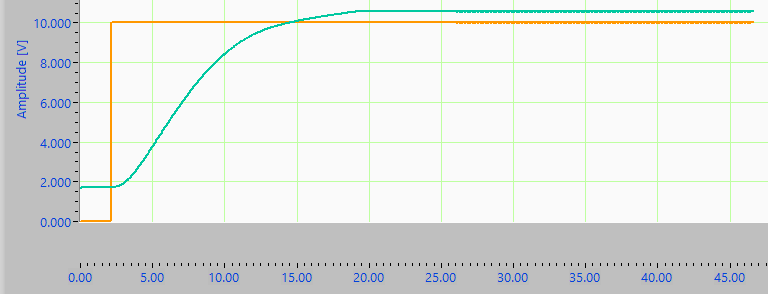

### Text = 10°

2v

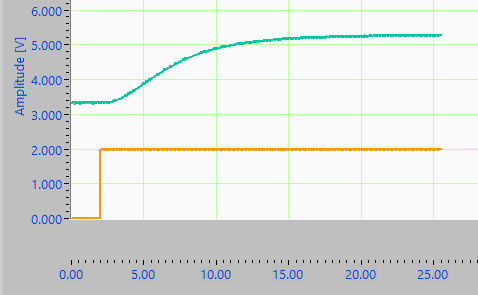

4v

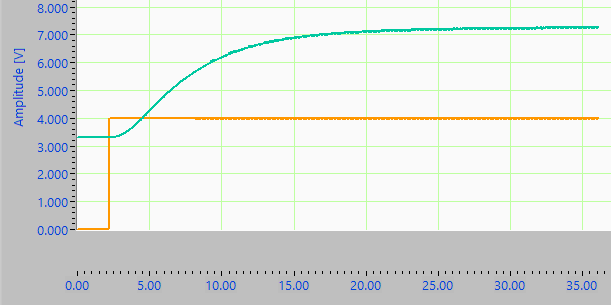

6v

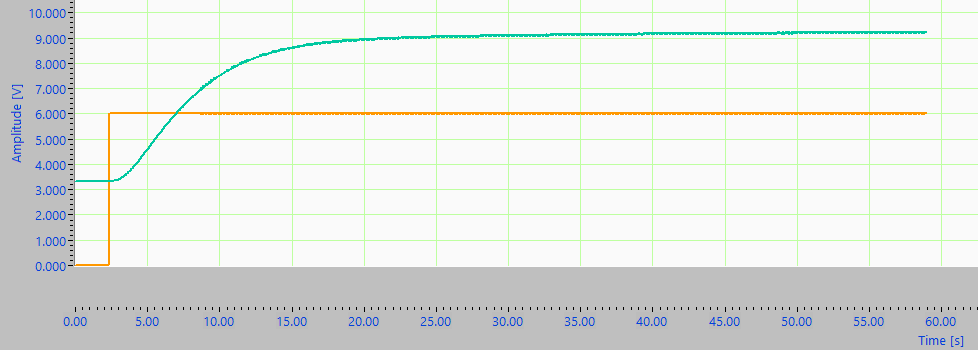

8v (sature)

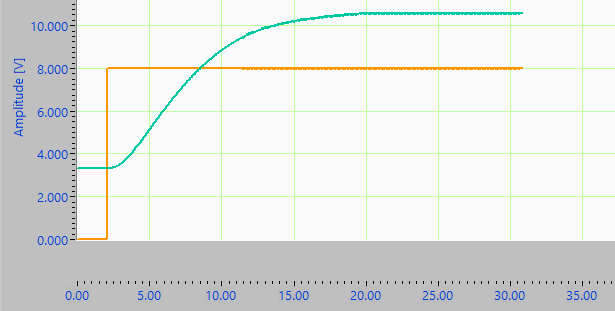

10v (sature)